clear
clc

% ///////////////////// INPUT \\\\\\\\\\\\\\\\\\\\\\\

prompt = 'Type in the name of the folder with the frames: ';
folderName = input(prompt,'s');

prompt = ['Choose the segmentation algorithm:\n    ' ...
    '1) Own implementation of segmentation based on histogram binarization\n    ' ...
    '2) Segementation based on adaptive binarization\n    ' ...
    '3) Otsu Binarization\n    ' ...
    '4) Niblack Binarization\n    ' ...
    '5) Sauvola Binarization\n    ' ...
    '6) Mean value Binarization\n    ' ...
    '7) Kapur entropy Binarization\n   ' ...
    '8) Watershed segmentation with markers based on local minima/maxima\n    ' ...
    '9) Kmeans segmentation\n    ' ...
    '10) Watershed segmentation with markers based on color using kmeans\n    ' ...
    '11) Mixed bag\n\n'];
implementation = input(prompt);

folderPath = '';
filePath = ''; 
switch implementation
    case 1
        folderPath = ['ownResults_' folderName]
        filePath = [folderPath '\ownBinarization_']
    case 2
        folderPath = ['adaptiveResults_' folderName]
        filePath = [folderPath '\adaptiveBinarization_']
    case 3
        folderPath = ['otsuResults_' folderName]
        filePath = [folderPath '\otsuBinarization_']
    case 4
        folderPath = ['niblackResults_' folderName]
        filePath = [folderPath '\niblackBinarization_']
    case 5
        folderPath = ['sauvolaResults_' folderName]
        filePath = [folderPath '\sauvolaBinarization_']
    case 6
        folderPath = ['meanResults_' folderName]
        filePath = [folderPath '\meanBinarization_']
    case 7
        folderPath = ['kapurResults_' folderName]
        filePath = [folderPath '\kapurBinarization_']
    case 8
        folderPath = ['watershedResults_' folderName]
        filePath = [folderPath '\watershedSegmentation_']
    case 9
        folderPath = ['kmeansResults' folderName]
        filePath = [folderPath '\kmeansSegmentation_']
    case 10
        folderPath = ['watershedResults_' folderName]
        filePath = [folderPath '\watershedSegmentation_']
    case 11
        folderPath = ['mixBagResults_' folderName]
        filePath = [folderPath '\mixBagSegmentation_']
    otherwise
        errordlg('Choose a valid segmentation algorithm','Input Error')
        return
end

folderPath = 'sauvolaResults_sick1'

filePath = 'sauvolaResults_sick1\sauvolaBinarization_'


% Feature Choosing
if implementation > 0 && implementation < 8
    prompt = ['Choose the segmentation feature: \n    ' ...
        '1) Gray level\n    ' ...
        '2) Red level\n    ' ...
        '3) Green level\n    ' ...
        '4) Blue level\n'];
elseif implementation > 7 && implementation < 11
    prompt = ['Choose the segmentation feature: \n    ' ...
        '5) RGB color space\n    ' ...
        '6) L*a*b* color space\n\n'];
end
feature = input(prompt);
% Case of mixbag implementation
if implementation > 11
    feature = -1;
end

% Preprocessing of the image
prompt = ['Do you want to use preprocessing of the frame? (y/n)'];
preproc = input(prompt,"s");

% Folder creation to store results
if exist(folderPath, 'dir')
    rmdir(folderPath,'s');
end
mkdir(folderPath);

% Desired frame range 
prompt = 'Choose the number of the inital frame:';
initalFrame = input(prompt);
prompt = 'Choose the number of the final frame:';
finalFrame = input(prompt);

% Declaration of variables and default values
global S frameIx  previousThreshold previousCentroid previousArea previousAperture apertureThreshold
S = dir(fullfile(['.\' folderName '\'],'*.jpg'));
S = natsortfiles(S);
% Variables
frames = {};
discardedFrames = {};

apertures = [];
aperture = -1;
areas = [];

previousThreshold = -1;
previousCentroid = [0 0];
previousArea = -1;
previousAperture = -1;
apertureThreshold = 0.8; % Scalar from 0 to 1

minimumAperture = 7;

maximumConsecutiveMisses = 2;
consecutiveMisses = 0; % Counter of the number of consecutive misses

meanReds = [];
meanGreens = [];
meanBlues = [];

first = true;

% initializing progress bar
f = waitbar(0,'Obtaining frames...');
for frameIx = initalFrame:finalFrame
    
    frameName = fullfile(['.\' folderName],S(frameIx).name)
    frame = imread(frameName);
    
    % updating progress bar
    percentage = (frameIx - initalFrame)/(finalFrame - initalFrame);
    waitbar(percentage,f,'Processing frames...'); 

%     figure
%     imshow(frame);
%     title('Original Frame');
    
    % //////// PREPROCESSING \\\\\\\\\\
    % ------- Image Cropping ----------
    frameCropped = imcrop(frame,[168,54,387,458]);
    
%     figure
%     imshow(frameCropped);
%     title('Cropped Frame');
    
    % ---------------------------------
    
    % Variables actualization
    validFrame = true;
    % Setting the previous centroid to the center of the image for the first treated
    % frame
    if first
        previousCentroid = [size(frameCropped,1)/2,size(frameCropped,2)/2];
        first = false;
    end
        
    % ---------- Channels -------------
    redChannel = frameCropped(:,:,1);
    greenChannel = frameCropped(:,:,2);
    blueChannel = frameCropped(:,:,3);
    
    % Create an all black channel.
    allBlack = zeros(size(frameCropped, 1), size(frameCropped, 2), 'uint8');
    % Create a color version of each Channel
    frameRed = cat(3, redChannel, allBlack, allBlack);
    frameGreen = cat(3, allBlack, greenChannel, allBlack);
    frameBlue = cat(3, allBlack, allBlack, blueChannel);
    % ---------------------------------
    
    % ---------- Gray scale -----------
    frameGray = rgb2gray(frameCropped);
    % ---------------------------------
    
    % ------------ Prints -------------
    % Print red channel
%     figure
%     imshow(frameRed);
%     title('Red Channel only');
    % Print green channel
%     figure
%     imshow(frameGreen);
%     title('Green Channel only');
    % Print blue channel
%     figure
%     imshow(frameBlue);
%     title('Blue Channel only');
    % Gray scale print
%     figure
%     imshow(frameGray);
%     title('Gray scale');
    % ----------------------------------
        
    preProcessedFrame = [];
    % Filterage of frame
    switch  feature
        case 1
            preProcessedFrame = frameGray;
            if preproc == 'y'
                preProcessedFrame = openCloseByReconstruction(preProcessedFrame);
            end
        case 2
            preProcessedFrame = redChannel;
            if preproc == 'y'
                preProcessedFrame = openCloseByReconstruction(preProcessedFrame);
            end
        case 4
            preProcessedFrame = greenChannel;
            if preproc == 'y'
                preProcessedFrame = openCloseByReconstruction(preProcessedFrame);
            end
        case 5
            preProcessedFrame = blueChannel;
            if preproc == 'y'
                preProcessedFrame = openCloseByReconstruction(preProcessedFrame);
            end
        case 6
            preProcessedFrame = frameCropped;
            if preproc == 'y'
                preProcessedRChannel = openCloseByReconstruction(redChannel);
                preProcessedGChannel = openCloseByReconstruction(greenChannel);
                preProcessedBChannel = openCloseByReconstruction(blueChannel);
                preProcessedFrame = cat(3,preProcessedRChannel,preProcessedGChannel,preProcessedBChannel);
            end
        case 7
            preProcessedFrame = frameCropped;
            if preproc == 'y'
                preProcessedRChannel = openCloseByReconstruction(redChannel);
                preProcessedGChannel = openCloseByReconstruction(greenChannel);
                preProcessedBChannel = openCloseByReconstruction(blueChannel);
                preProcessedFrame = cat(3,preProcessedRChannel,preProcessedGChannel,preProcessedBChannel);
            end
            % Change the color scheme from RGB to L*a*b* (Luminance, Green/Red tones, Blue/Yellow tones)
            preProcessedFrame = rgb2lab(preProcessedFrame);
    end
    
%     imshow(preProcessedFrame);
%     title('Preprocessed Frame')

    % \\\\\\\\\\\\\\\|/////////////////
    
    % ///////// BINARIZATION AND SEGMENTATION \\\\\\\\\\
        
    binFrame = [];
    switch implementation
        case 1
            try
                % Own binaritzation
                binFrame = binBinarization(preProcessedFrame,10,preproc);
            catch
                sprintf('Error during binBinarization in frame %d',frameIx)
                validFrame = false;
            end
        case 2
            try
                % Adaptive binarization
                binFrame = imbinarize(preProcessedFrame,"adaptive", ...
                    "ForegroundPolarity","bright","Sensitivity",0.66);
                binFrame = ~binFrame;
            catch
                sprintf('Error during adaptiveBinarization in frame %d',frameIx)
                validFrame = false;
            end
        case 3
            try
                % Otsu binarization
                level = graythresh(preProcessedFrame);
                binFrame = ~imbinarize(preProcessedFrame,level);
            catch
                sprintf('Error during Otsu binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 4
            try
                % Niblack binarization
                binFrame = ~niblack(preProcessedFrame, ...
                    [ceil(size(preProcessedFrame,2)*0.6),ceil(size(preProcessedFrame,1)*0.6)]);
            catch
                sprintf('Error during Otsu binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 5
            try
                % Sauvola binarization
                binFrame = ~sauvola(preProcessedFrame, ...
                    [ceil(size(preProcessedFrame,2)*0.6),ceil(size(preProcessedFrame,1)*0.6)]);
            catch
                sprintf('Error during Sauvola binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 6
            try
                % Mean value binarization
                level = mean2(preProcessedFrame);
                binFrame = preProcessedFrame <= level;
            catch
                sprintf('Error during SauvolaRidler-Calvard binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 7
            try
                % Kapur entropy binarization
                binFrame = ~kapur(preProcessedFrame);
            catch
                sprintf('Error during Kapur entropy binarization in frame %d',frameIx)
                validFrame = false;
            end
        case 8 
            try
                % kmeans segmentation
                if feature == 7
                    [~, binFrame, ~, ~] = kmeansLabSegmentation(preProcessedFrame,8,0);
                elseif feature == 6 || feature == 8
                    [binFrame, ~, ~, ~] = kmeansRGBSegmentation(preProcessedFrame,8,0); 
                end
            catch
                sprintf('Error during Kmeans segementation in frame %d',frameIx)
                validFrame = false;
            end
        case 9
            try
                % Watershed segmentation
                binFrame = watershedSegmentation(preProcessedFrame, frameCropped, preproc);
            catch
                sprintf('Error during Watershed segmentation in frame %d',frameIx)
                validFrame = false;
            end
        case 10
            try
                % watershed segmentation using kmeans to extract markers
                binFrame = watershedSegmentationKmeans(preProcessedFrame, preproc);
            catch
                sprintf('Error during Kmeans segementation in frame %d',frameIx)
                validFrame = false;
            end
        case 11
            try
                % mixBag Segmentation (combination of various techniques)
                [closeDiffBlobFrame, aperture, cols, rows, centroid, area, bbox, midpoint] = mixBagSegmentation( ...
                    preProcessedFrame, frameCropped, preproc);
            catch 
                sprintf('Error during mix-bag segmentation in frame %d',frameIx)
                validFrame = false;
            end
    end
        
%     figure
%     imshow(binFrame)

    % ---------------------------------
    % \\\\\\\\\\\\\\\|/////////////////
    
    % //////// POSTPROCESSING \\\\\\\\\\
    try
        if validFrame && implementation ~= 12
            closeDiffBlobFrame = getSegment(binFrame);
        end
    catch
        sprintf('Error during funciton getSegmet of frame %d', frameIx)
        validFrame = false;
    end
%     figure
%     imshow(closeDiffBlobFrame)
    % \\\\\\\\\\\\\\\|/////////////////
    
    % Getting the area
    if validFrame
        maxDiffArea = bwarea(closeDiffBlobFrame);
    end
    
    if validFrame
        try
            [aperture, cols, rows, centroid, area, bbox, midpoint] = getStenosisDegree(frameCropped, ...
                closeDiffBlobFrame);
        catch
            sprintf('Error while getting the stenosis degree of frame %f', frameIx)
        end
        if previousAperture == -1 && aperture > minimumAperture
            previousAperture = aperture;
        elseif aperture < minimumAperture
            validFrame = false;
        end
    end
    % \\\\\\\\\\\\\\\|/////////////////

    % ---------- Saving results -------------- %
    validAperture = false;
    if validFrame
        if ~isempty(aperture) 
            if (aperture < previousAperture + previousAperture*apertureThreshold && ...
                aperture > previousAperture - previousAperture*apertureThreshold) && ...
                aperture > minimumAperture
            validAperture = true;
            end 
        end
    end
    
    if validFrame && validAperture
        frames{end + 1} = S(frameIx).name;
        apertures = [apertures aperture];
        previousAperture = aperture;
        previousCentroid = centroid;
        previousArea = maxDiffArea;
        consecutiveMisses = 0;
        
        meanRed = mean(redChannel(closeDiffBlobFrame));
        meanGreen = mean(greenChannel(closeDiffBlobFrame));
        meanBlue = mean(blueChannel(closeDiffBlobFrame));
        meanReds = [meanReds meanRed];
        meanGreens = [meanGreens meanGreen];
        meanBlues = [meanBlues meanBlue];
        
        % Plot of all the data on top of the original image
        edgeDetected = edge(closeDiffBlobFrame,"canny");
        frameOutlined = imoverlay(frameCropped,edgeDetected,'yellow');
        firstFig = figure('visible','off');
        imshow(frameOutlined);
        
        hold on;
        plot(cols,rows,'c','LineWidth',2)
        plot(centroid(1), centroid(2), 'r+', 'LineWidth', 2, 'MarkerSize', 7)
        rectangle('Position',bbox,"EdgeColor",'b')
        title('Segmentation outline with the degree of stenosis');
        text(midpoint(2) + 20,midpoint(1),string(aperture),'Color',[0 1 1],'FontSize',8)
        saveas(firstFig,[pwd ['\' filePath] S(frameIx).name]);
        
    elseif consecutiveMisses < maximumConsecutiveMisses
        frames{end + 1} = S(frameIx).name;
        apertures = [apertures -1];
        consecutiveMisses = consecutiveMisses + 1;
        
        meanReds = [meanReds -1];
        meanGreens = [meanGreens -1];
        meanBlues = [meanBlues -1];
        
        firstFig = figure('visible','off');
        imshow(frameCropped);
        title('Missed Frame');
        saveas(firstFig,[pwd ['\' filePath] S(frameIx).name]);
        
    else
        previousThreshold = -1;
        previousAperture = -1;
        previousArea = -1;
        
        discardedFrames{end + 1}= S(frameIx).name;
        consecutiveMisses = consecutiveMisses + 1;
    end
    % ---------------------------------------- %
end 

frameName = '.\sick1\1.jpg'


% closing progress bar
close(f)

% ///////////// RESULTS \\\\\\\\\\\\\\\

T = table(frames',apertures',meanReds',meanGreens',meanBlues')

T = 1×5 table
      Var1        Var2      Var3      Var4      Var5 
    _________    ______    ______    ______    ______

    {'1.jpg'}    81.707    111.37    60.186    57.485


% Standard Deviation of the valid apertures
variance = var(apertures)

variance = 0

standardDeviation = std(apertures)

standardDeviation = 0

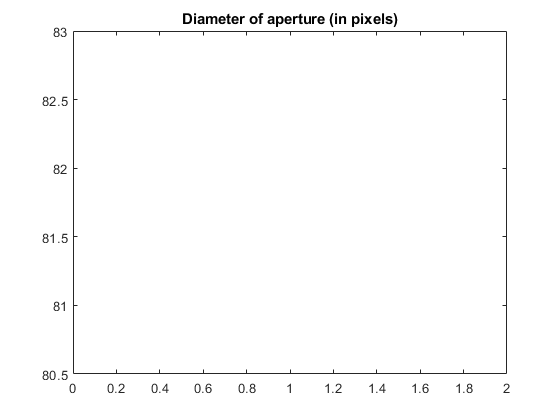


figure
plot(apertures)
title('Diameter of aperture (in pixels)')


apertures = rmoutliers(apertures,'movmedian',(finalFrame - initalFrame)*0.3);

Error using isoutlier>parseinput (line 219)
Window length argument must be a numeric or duration finite positive scalar or 2-element numeric or duration finite nonnegative vector.

Error in isoutlier (line 95)
[method, wl, dim, p, sp, vars, maxoutliers, lowup] = parseinput(a, varargin);

Error in 

plot(apertures)
title('Diameter of aperture without outliers')

% Finding peaks
peaksIx = [1:size(apertures)];
[peaks, locs, p] = findpeaks(apertures,peaksIx,'Annotate','extents');
figure
findpeaks(apertures,peaksIx,'Annotate','extents')

figure
plot(locs,peaks)
title('Diameter peaks of the apertures')

% Getting the biggest difference in the peaks
[minVal, minIx] = min(peaks);
[maxVal, maxIx] = max(peaks);
result = maxVal - minVal;

% Getting the difference on the degree of stenosis
degreeDiff = 100 - (minVal*100 / maxVal);

% Printing the results
formatStruct.Interpreter = 'tex';
formatStruct.WindowStyle = 'modal';
if degreeDiff > 50
    msgbox(sprintf('The patient has tracheobronchomalacia with a degree of stenosis of %.2f %%',degreeDiff),'Diagnosis',formatStruct)
else
    msgbox('The patient does not have tracheobronchomalacia','Diagnosis',formatStruct)
end

% \\\\\\\\\\\\\\\\\//////////////////

function [segment, aperture, cols, rows, centroid, area, bbox, midpoint] = mixBagSegmentation(frame, frameCropped, preproc)
    global previousArea previousAperture apertureThreshold
    
    % Kmeans segmentation
    [kmeansMask, kmeansRRange, kmeansGRange, kmeansBRange] = kmeansRGBSegmentation(frame,8,0);
    % Watershed segmentation with marks based on kmeans
    watershedMask = watershedSegmentationKmeans(frame, preproc);
    % Own binarization based on Image histogram using the red color range of the
    % image
    redFrame = frame(:,:,1);
    binMask = binBinarization(redFrame,10,preproc);
    
    kmeansValid = true;
    try
        kmeansFrame = getSegment(kmeansMask);
    catch
        sprintf('Error during postprocessing of kmeans frame during mixBag.')
        kmeansValid = false;
    end
    binValid = true;
    try
        binFrame = getSegment(binMask);
    catch
        sprintf('Error during postprocessing of own binarization frame during mixBag.')
        binValid = false;
    end
    watershedValid = true;
    try
        watershedFrame = getSegment(watershedMask); 
    catch
        sprintf('Error during postprocessing of watershed frame during mixBag.')
        watershedValid = false;
    end
    
    selection = 0;
    redChannel = frameCropped(:,:,1);
    if kmeansValid
        [kmeansAperture, kmeansCols, kmeansRows, kmeansCentroid, kmeansArea, kmeansBbox, kmeansMidpoint, kmeansMAL] = getStenosisDegree( ...
            frameCropped, kmeansFrame);
        meanRChannelKmeans = mean(redChannel(kmeansFrame));

        if previousAperture ~= -1
            if kmeansAperture >= previousAperture + previousAperture*apertureThreshold|| ...
                kmeansAperture <= previousAperture - previousAperture*apertureThreshold
                kmeansValid = false;
            end
        end
        if previousArea ~= -1
            if kmeansArea >= previousArea + previousArea*0.75 || ...
                kmeansArea <= previousArea - previousArea*0.75
                kmeansValid = false;
            end
        end
    end
    if binValid
        [binAperture, binCols, binRows, binCentroid, binArea, binBbox, binMidpoint, binMAL] = getStenosisDegree( ...
            frameCropped, binFrame);
        
        if previousAperture ~= -1
            if binAperture >= previousAperture + previousAperture*apertureThreshold || ...
                binAperture <= previousAperture - previousAperture*apertureThreshold
                binValid = false;
            end 
        end
        if previousArea ~= -1
            if binArea >= previousArea + previousArea*0.75 || ...
                binArea <= previousArea - previousArea*0.75
                binValid = false;
            end
        end
    end
    if watershedValid
        [watershedAperture, watershedCols, watershedRows, watershedCentroid, watershedArea, watershedBbox, watershedMidpoint, watershedMAL] = getStenosisDegree( ...
            frameCropped, watershedFrame);
       
        if previousAperture ~= -1
            if watershedAperture >= previousAperture + previousAperture*apertureThreshold || ...
                watershedAperture <= previousAperture - previousAperture*apertureThreshold
                watershedValid = false;
            end 
        end
        if previousArea ~= -1
            if watershedArea >= previousArea + previousArea*0.75 || ...
                watershedArea <= previousArea - previousArea*0.75
                watershedValid = false;
            end
        end
    end
        
    % Evaluate Results
    if kmeansValid
        if binValid
            if kmeansAperture > 80 || (kmeansAperture > 50 && (kmeansAperture <= 80 && meanRChannelKmeans < 60)) || kmeansMAL > 2*kmeansAperture
                selection = 1;
            end
        else
            if watershedValid
                if kmeansAperture > 80 || (kmeansAperture > 50 && (kmeansAperture <= 80 && meanRChannelKmeans < 60)) || kmeansMAL > 2*kmeansAperture
                    selection = 2;
                end 
            end
        end
    else
        if binValid
            selection = 1;
        elseif watershedValid
            selection = 2;
        else
            selection = -1;
        end
    end
    
    if selection == 0
        sprintf('kmeansSegmentation Used')
        
        segment = kmeansFrame;
        aperture = kmeansAperture;
        cols = kmeansCols;
        rows = kmeansRows;
        centroid = kmeansCentroid;
        area = kmeansArea;
        bbox = kmeansBbox;
        midpoint = kmeansMidpoint;
    elseif selection == 1
        sprintf('ownSegmentation Used')
        
        segment = binFrame;
        aperture = binAperture;
        cols = binCols;
        rows = binRows;
        centroid = binCentroid;
        area = binArea;
        bbox = binBbox;
        midpoint = binMidpoint;
    elseif selection == 2
        sprintf('watershed Segmentation Used')
        
        segment = watershedFrame;
        aperture = watershedAperture;
        cols = watershedCols;
        rows = watershedRows;
        centroid = watershedCentroid;
        area = watershedArea;
        bbox = watershedBbox;
        midpoint = watershedMidpoint;
    else
        segment = [];
        aperture = -1;
        cols = [];
        rows = [];
        centroid = [];
        area = 0;
        bbox = [];
        midpoint = [];
    end
end

function [mask, clusterRRange, clusterGRange, clusterBRange] = kmeansRGBSegmentation(frame, k, flagOuterMarks)

    % Separating the 3 different dimensions
    R = frame(:,:,1);
    G = frame(:,:,2);
    B = frame(:,:,3);
    
    % Applying kmeans
    [labels, centroids]= imsegkmeans(frame,k,"NumAttempts",3);
        
%     C = labeloverlay(frame,labels);
%     figure
%     imshow(C)
%     title("Labeled Image RGB")
    
    minR = 255; % Red channel minimum intensity 
    minG = 255; % Green channel minimum intensity 
    minB = 255; % Blue channel minimum intensity 
    maxR = 0; % Red channel maximum intensity 
    maxG = 0; % Green channel maximum intensity 
    maxB = 0; % Blue channel maximum intensity
    ix = 0; % Index of the cluster to return
    count = 0;
    for i = 1:k 
        % Mask applied to input image
        mask = labels == i;
%         cluster = frame.*uint8(mask);
%         figure
%         imshow(cluster)
%         title("RGB Cluster "+i);
        
        if flagOuterMarks == 0
            % Minimum values of ligth intensity for each channel in the cluster
            auxMinR = min(R(mask > 0));
            auxMinG = min(G(mask > 0));
            auxMinB = min(B(mask > 0));
            
            % Count the number of channels that has lower values that the current
            % lowest
            if minR > auxMinR
                count = count + 1;
            end
            if minG > auxMinG
                count = count + 1;
            end
            if minB > auxMinB
                count = count + 1;
            end
            
            % If 2 or more channels has less lighting I select it as the well
            % channel
            if count >= 2
                ix = i;
                minR = auxMinR;
                minG = auxMinG;
                minB = auxMinB;
            end
        else
            % Minimum values of ligth intensity for each channel in the cluster
            auxMaxR = max(R(mask > 0));
            auxMaxG = max(G(mask > 0));
            auxMaxB = max(B(mask > 0));
            
            % Count the number of channels that has lower values that the current
            % lowest
            if maxR < auxMaxR
                count = count + 1;
            end
            if maxG < auxMaxG
                count = count + 1;
            end
            if maxB < auxMaxB
                count = count + 1;
            end
            
            % If 2 or more channels has less lighting I select it as the well
            % channel
            if count >= 2
                ix = i;
                maxR = auxMaxR;
                maxG = auxMaxG;
                maxB = auxMaxB;
            end
        end
        
        count = 0;
    end

    % Mask of the resulting cluster
    mask = labels == ix;
    
    % Range of values on the Red spectrum
    clusterRRange = [min(R(mask > 0)) max(R(mask > 0))];
    % Range of values on the Green spectrum
    clusterGRange = [min(G(mask > 0)) max(G(mask > 0))];
    % Range of values on the Blue spectrum
    clusterBRange = [min(G(mask > 0)) max(G(mask > 0))];
    
%     B = labels .* uint8(mask);
%     C = labeloverlay(frame,B);
%     imshow(C)
%     title("Labeled Image with Additional Pixel Information")
end

function [labFrame, mask, clusterGRRange, clusterBYRange] = kmeansLabSegmentation(frame, k)
    
    % Separating the 3 different dimensions
    imLuminance = frame(:,:,1);
    ab = frame(:,:,2:3);
    ab = im2single(ab);
    a = ab(:,:,1);
    b = ab(:,:,2);
    
    % Applying kmeans only to the color dimensions
    labels = imsegkmeans(ab,k,"NumAttempts",3);
    
    B = labeloverlay(frame,labels);
%     figure
%     imshow(B)
%     title("Labeled Image a*b*")
    
    wellIx = 0; % Index of the cluster to return
    minimalLuminance = 100; % Luminance in L*a*b* goes from [0 to 100]
    for i = 1:k 
        % Mask applied to input image
        mask = labels == i;
        cluster = frame.*uint8(mask);
%         figure
%         imshow(cluster)
%         title("Cluster "+i);
        
        % Getting the luminance of the cluster
        luminance = imLuminance.*mask;
        
        % Minimum value of luminance per cluster
        maskMinLuminance = min(luminance(luminance > 0));
        
        % Storing the index of the cluster with less luminance
        if maskMinLuminance < minimalLuminance
            minimalLuminance = maskMinLuminance;
            wellIx = i;
        end
    end
    
    % Mask of the resulting cluster
    mask = labels == wellIx;
    % Range of values on the green/red spectrum
    clusterGRRange = [min(a(mask > 0)) max(a(mask > 0))];
    % Range of values on the blue/yellow spectrum
    clusterBYRange = [min(b(mask > 0)) max(b(mask > 0))];
end

function watershedSegmentation = watershedSegmentationKmeans(frame, preproc)

    [outerMostRegion, ~, ~, ~] = kmeansRGBSegmentation(frame, 2, 1);
%     figure
%     imshow(outerMostRegion)
%     title('Regional outerMostRegion')
    
    innerMostRegion= kmeansRGBSegmentation(frame, 14, 0);
%     figure
%     imshow(innerMostRegion)
%     title('Regional Minimums')

    imGray = rgb2gray(frame);
    % If the frame hasn't been preprocessed, we preprocessed it in order to get
    % good regional minimas and maximas
    if preproc == 'n'
        grayProcessed = openCloseByReconstruction(imGray);
    else
        grayProcessed = imGray;
    end
    % Regional minimas and maximas
    minimas = imregionalmin(grayProcessed);
    maximas = imregionalmax(grayProcessed);
    
    minimas = minimas & ~innerMostRegion;
    outerMostRegion = outerMostRegion | minimas | maximas;
    
    se = strel(ones(5,5));
    innerMostRegion = imclose(innerMostRegion,se);
    innerMostRegion = imerode(innerMostRegion,se);
    innerMostRegion = bwareaopen(innerMostRegion,50);
    
    outerMostRegion = imclose(outerMostRegion,se);
    outerMostRegion = imerode(outerMostRegion,se);
    outerMostRegion = bwareaopen(outerMostRegion,50);
    
%     figure
%     imshow(outerMostRegion)
%     title('Outer-Most Regions')
    
%     figure
%     imshow(innerMostRegion)
%     title('Inner-Most Regionals')
    
    D = bwdist(outerMostRegion | innerMostRegion);
    DL = watershed(D);
    bgm = DL == 0;
%     figure
%     imshow(bgm)
%     title('Watershed Ridge Lines')
    
    I2 = labeloverlay(frame,innerMostRegion | outerMostRegion);
%     figure
%     imshow(I2)
%     title('Regional Minimum and Maxima Superimposed on Frame')
    
    % Gradient of the image
    gmag = imgradient(grayProcessed);
%     figure
%     imshow(gmag,[]);
%     title('Image gradient')
    
    fgm = (innerMostRegion | outerMostRegion);
    gmag2 = imimposemin(gmag, fgm);
%     figure
%     imshow(gmag2,[])
%     title('Gradient with markers imposed')
    
    L = watershed(gmag2);
    labels = imdilate(L==0,ones(3,3)) + 2*(innerMostRegion | outerMostRegion) + 3*fgm;
    I4 = labeloverlay(frame,labels);
%     figure
%     imshow(I4)
%     title('Markers and Object Boundaries Superimposed on Frame')
    
    % labeling the watershed results
    Lrgb = label2rgb(L,'jet','w','shuffle');
%     figure
%     imshow(Lrgb)
%     title('Colored Watershed Label Matrix')
    
    % Getting the the value of the labels for the biggest minimum blob in the frame
    labelValue = L(innerMostRegion);
    % Getting the labels of the inner-most regions
    values = unique(labelValue(:,1));
    % Getting the watershed segmentation of the stenosis level
    watershedSegmentation = zeros(size(L,1), size(L,2));
    for i = 1:size(values)
        watershedSegmentation = watershedSegmentation | L == values(i);
    end
    I5 = labeloverlay(frame,watershedSegmentation);
%     figure
%     imshow(I5)
%     title('Watershed final mask')
end


function watershedSegmentation = watershedSegmentation(preProcessedFrame, frameCropped, preproc)
    % If the frame hasn't been preprocessed, we preprocessed it in order to get
    % good regional minimas and maximas
    if preproc == 'n'
        preProcessedFrame = openCloseByReconstruction(preProcessedFrame);
    end
    
    maximums = imregionalmax(preProcessedFrame);
%     figure
%     imshow(maximums)
%     title('Regional maximums')
    
    minimums = imregionalmin(preProcessedFrame);
%     figure
%     imshow(minimums)
%     title('Regional Minimums')
    
    minimum = extractClosestBlob(minimums, [size(frameCropped,1) / 2 size(frameCropped,2) / 2]);
%     figure
%     imshow(minimum)
%     title('Biggest minimum')
    
    D = bwdist(maximums | minimums);
    DL = watershed(D);
    bgm = DL == 0;
%     figure
%     imshow(bgm)
%     title('Watershed Ridge Lines')
    
    I2 = labeloverlay(frameCropped,minimums | maximums);
%     figure
%     imshow(I2)
%     title('Regional Minimum and Maxima Superimposed on Frame)
    
    se2 = strel(ones(5,5));
    fgm2 = imclose(minimums | maximums,se2);
    fgm3 = imerode(fgm2,se2);
    fgm4 = bwareaopen(fgm3,20);
    I3 = labeloverlay(frameCropped,fgm4);
%     figure
%     imshow(I3)
%     title('Modified Regional Maxima Superimposed on Frame')
    
    % Gradient of the image
    gmag = imgradient(preProcessedFrame);
%     figure
%     imshow(gmag,[]);
%     title('Image gradient')
    
    gmag2 = imimposemin(gmag, fgm4);
%     figure
%     imshow(gmag2,[])
%     title('Gradient with markers imposed')
    L = watershed(gmag2);
    labels = imdilate(L==0,ones(3,3)) + 2*(minimums | maximums) + 3*fgm4;
    I4 = labeloverlay(frameCropped,labels);
%     figure
%     imshow(I4)
%     title('Markers and Object Boundaries Superimposed on rame')
    % labeling the watershed results
    Lrgb = label2rgb(L,'jet','w','shuffle');
%     figure
%     imshow(Lrgb)
%     title('Colored Watershed Label Matrix')
    % Getting the the value of the labels for the biggest minimum blob in the frame
    labelValue = L(minimum);
    % Getting the label with maximum ocurrence
    value = mode(labelValue);
    % Getting the watershed segmentation of the stenosis level
    watershedSegmentation= L == value;
%     figure
%     imshow(watershedSegmentation);
%     title('Watershed final mask')
end

function [aperture, cols, rows, segmentCentroid, area, bbox, midpoint, minorAxisLen] = getStenosisDegree(frameCropped, frameMask)
    global S frameIx previousCentroid
    %  --------- Getting the degree of aperture and saving the image -------
        % Max diff result
        edgeDetected = edge(frameMask,"canny");
%         frameOutlined = imoverlay(frameCropped,edgeDetected,'yellow');
        
%         firstFig = figure('visible','off');
%         firstFig = figure;
%         imshow(frameOutlined);
    
        stats = regionprops(frameMask, 'Centroid', 'BoundingBox', ...
            'Orientation', 'MinFeretProperties', 'Area', 'MinorAxisLength');
        
        area = stats.Area;
        bbox = stats.BoundingBox;
        orientation = stats.Orientation; % Getting the perpendicular orientation
        minorAxisLen = stats.MinorAxisLength;
        
        if orientation < 45 && orientation > -45 
            xCentroid = bbox(1) + bbox(3)/2;
            yCentroid = stats.Centroid(2);
        else
            xCentroid = stats.Centroid(1);
            yCentroid = bbox(2) + bbox(4)/2;
        end
%         previousCentroid = [xCentroid yCentroid];
        
        % Calculating the aperture using the orientation of the blob
        % and the centroid
        sinOrient = sind(orientation);
        cosOrient = cosd(orientation);
        
        if orientation < 45 && orientation > -45 
            vertUpperDist = pdist([xCentroid, yCentroid; xCentroid, bbox(2), ],'euclidean');
            vertLowerDist = pdist([xCentroid, yCentroid; xCentroid, (bbox(2) + bbox(4))],'euclidean');
        else
            vertUpperDist = pdist([xCentroid, yCentroid; bbox(1), yCentroid, ],'euclidean');
            vertLowerDist = pdist([xCentroid, yCentroid; (bbox(1) + bbox(3)) ,yCentroid],'euclidean');
        end
        % Calculing the endpoints of the line of aperture from the centroid,
        % adding the relative distance to the bounding box plus a half
        xCoords(1) = xCentroid + (vertUpperDist + vertUpperDist/2) * sinOrient;
        yCoords(1) = yCentroid + (vertUpperDist + vertUpperDist/2) * cosOrient;
        xCoords(2) = xCentroid - (vertLowerDist + vertLowerDist/2) * sinOrient;
        yCoords(2) = yCentroid - (vertLowerDist + vertLowerDist/2) * cosOrient;
        
        % Distance between the two endpoints of the line
        nPoints = ceil(sqrt((xCoords(2) - xCoords(1)).^2 + (yCoords(2) - yCoords(1)).^2)) + 1;
        
        % X and Y values of the endpoints
        xvalues = round(linspace(xCoords(1), xCoords(2), nPoints));
        yvalues = round(linspace(yCoords(1), yCoords(2), nPoints));
        
        % Cropping the aperture pixels that surpass the bounding box of the blob
        if orientation < 135 && orientation > -45 
            xvalues(yvalues < bbox(2)) = [];
            yvalues(yvalues < bbox(2)) = [];
            xvalues(yvalues > (bbox(2) + bbox(4))) = [];
            yvalues(yvalues > (bbox(2) + bbox(4))) = [];
            
            yvalues(xvalues < bbox(1)) = [];
            xvalues(xvalues < bbox(1)) = [];
            yvalues(xvalues > (bbox(1) + bbox(3))) = [];
            xvalues(xvalues > (bbox(1) + bbox(3))) = [];
        else
            xvalues(yvalues < bbox(2)) = [];
            yvalues(yvalues < bbox(2)) = [];
            xvalues(yvalues > (bbox(2) + bbox(4))) = [];
            yvalues(yvalues > (bbox(2) + bbox(4))) = [];
            
            yvalues(xvalues < bbox(1)) = [];
            xvalues(xvalues < bbox(1)) = [];
            yvalues(xvalues > (bbox(1) + bbox(3))) = [];
            xvalues(xvalues > (bbox(1) + bbox(3))) = [];
        end
        
        % Mask the values of intercection of the line with the edge of the segmentation mask 
        lineMask = false(size(edgeDetected,1),size(edgeDetected,2));
        lineMask(sub2ind(size(lineMask), yvalues, xvalues)) = 1;
        
        % Dilating the line to ensure that it intersects with the edge
        lineMask = imdilate(lineMask,strel('line',5,orientation));
        lineMask = edgeDetected .* lineMask;
        
        % Values of the two farthest points of the line¡
        [row1,col1] = find(lineMask, 1, 'first');
        [row2,col2] = find(lineMask, 1, 'last');
        cols = [col1 col2];
        rows = [row1 row2];
        midpoint = ([row1 col1] + [row2 col2]).'/2;
        aperture = pdist([row1, col1; row2, col2],'euclidean');
        segmentCentroid = [xCentroid yCentroid];
        
        
        % Plot of all the data on top of the original image
%         hold on;
%         plot([col1,col2],[row1,row2],'c','LineWidth',2)
%         plot(xCentroid, yCentroid, 'r+', 'LineWidth', 2, 'MarkerSize', 7)
%         rectangle('Position',bbox,"EdgeColor",'b')
%         title('Segmentation outline with the degree of stenosis');
%         text(midpoint(2) + 20,midpoint(1),string(aperture),'Color',[0 1 1],'FontSize',8)
%         saveas(firstFig,[pwd path S(frameIx).name]);
end

function mask = binBinarization(frame,bins,preproc)
    global previousThreshold
    [counts,binLocations] = imhist(frame,bins);
    % Getting first local maxima in the hist with a threshold of 3500
    % I use this threshold to ignore small local peaks
    [pks,locs] = findpeaks(counts,'MinPeakHeight',3500);
    if not(isempty(pks)) 
        ix = locs(1) - 1; %indexing to the previous bin for the calculus
        % Setting the threshold using the % of divergence between bins
        countDiff = (counts(ix) * 100) / counts(ix + 1);
        binDiff = binLocations(ix + 1) - binLocations(ix);
        binThresh = binLocations(ix) + binDiff * ((100-countDiff)/100);
    else
        diffs = diff(counts);
        [~, diffIx] = max(diffs(diffs>=0));
        countDiff = (counts(diffIx) * 100) / counts(diffIx + 1);
        binDiff = binLocations(diffIx + 1) - binLocations(diffIx);
        binThresh = binLocations(diffIx) + binDiff * ((100-countDiff)/100);
    end
    
    % A 15% is substracted for fine tuning of the binarization, due to
    % overestimation of the threshold in case of not using
    % preprocessing
    if preproc == 'n'
        binThresh = binThresh - binThresh*0.125;
    end
        
    % The previous threshold is taken into account in order to get more
    % accurate results
    if previousThreshold ~= -1
        threshDiff = binThresh - previousThreshold;
        if threshDiff >= 0
            percentageOfDiff = previousThreshold*100 / binThresh;
            binThresh = binThresh - threshDiff*(percentageOfDiff/100);
        else
            percentageOfDiff = binThresh*100 / previousThreshold;
            binThresh = binThresh + abs(threshDiff)*(percentageOfDiff/100);
        end
    end
    previousThreshold = binThresh;
    mask = frame <= binThresh;
end

function segmentationOutline(frame, segmentation)
    edgeDetected = edge(segmentation,"canny");
    frameOutlined = imoverlay(frame,edgeDetected,'yellow');
    imshow(frameOutlined);
end

function openClosedImage = openCloseByReconstruction(frame)    

    se = strel('disk',20);
    % Erosion
    frameErode = imerode(frame,se);
%     figure
%     imshow(frameErode)
%     title('Erosion')
    % Opening using reconstruction of the erode frame 
    frameObR = imreconstruct(frameErode,frame);
%     figure
%     imshow(frameObR)
%     title('Opened by reconstruction')
    % Dilation of the opened frame
    frameObRDilated = imdilate(frameObR,se);
%     figure
%     imshow(frameObRDilated)
%     title('Opened by eeconstruction and dilated')
    % Open and Close by reconstruction
    frameOCRecon = imreconstruct(imcomplement(frameObRDilated),imcomplement(frameObR));
    openClosedImage = imcomplement(frameOCRecon);
%     figure
%     imshow(openClosedImage)
%     title('Opening-Closing by Reconstruction')
end

function binaryImage = extractClosestBlob(binaryImage, point)
    try
      % Get all the Centroids
      [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
      blobStats = regionprops(labeledImage, 'Centroid');
      allCentroids = [blobStats.Centroid];
      allCentroids = reshape(allCentroids,2,[]).';
        
      % Get the closest Blob to the point
      [k, dist] = dsearchn(point,allCentroids);
      [~, ixStats] = min(dist);
      
      % Extract the blob using ismember().
      biggestBlob = ismember(labeledImage, ixStats);
      % Convert from integer labeled image into binary (logical) image.
      binaryImage = biggestBlob > 0;
      
    catch ME
      errorMessage = sprintf('Error in function extractClosestBlob().\n\nError Message:\n%s', ME.message);
      fprintf(1, '%s\n', errorMessage);
      uiwait(warndlg(errorMessage));
    end
end

function segmentFrame = getSegment(binFrame)
    global previousCentroid
    
    % -------- Filling holes ----------
    filledFrame = imfill(binFrame,8,'holes');
%     figure
%     imshow(filledFrame);
%     title('Binarization with filled holes');
    % ---------------------------------
    
    % ---------- Closing gaps ---------
    % With disks
    % SE = strel('disk',15,8);
    % closedFrame = imclose(filledFrame,SE);
    % imshow(closedFrame); % Circle closed
    % closedFilledFrame = imfill(closedFrame,8,'holes');
    % imshow(closedFilledFrame);
    
    % With lines
    positiveSlope = strel('line',15,45);
    negativeSlope = strel('line',15,-45);
    horizontalLine = strel('line',15,0);
    verticalLine = strel('line',15,90);
    closedFrame=imclose(filledFrame,positiveSlope);
    closedFrame=imclose(closedFrame,negativeSlope);
    closedFrame=imclose(closedFrame,horizontalLine);
    closedFrame=imclose(closedFrame,verticalLine);
    closedFilledFrame = imfill(closedFrame,8,'holes');
    
%     figure
%     imshow(closedFilledFrame);
%     title('Closed frame with gaps filled');
    
    % ---------------------------------
    
    % -- Removing small Conn. Comp. ---
    props = regionprops(closedFilledFrame, 'Area');
    allAreas = [props.Area];
    cleanedFrame = bwareaopen(closedFilledFrame, ceil(max(allAreas)*0.3));
    
    props = regionprops(cleanedFrame, 'Centroid', 'BoundingBox');
    CC = bwconncomp(cleanedFrame);
    L = labelmatrix(CC);
    % If there are more than on blob, I get the closest to the centroid of
    % the last frame with a valid centroid
    ixProps = 1; % Index of the stats struct
    centroid = [];
    if numel(props) > 1
        centroids = [props.Centroid];
        centroids = reshape(centroids,2,[]).';
        [k, dist] = dsearchn(previousCentroid,centroids);
        [~, ixProps] = min(dist);
        centroid = props(ixProps).Centroid;
    else
        centroid = props.Centroid;
    end
    
    cleanedFrame = L == ixProps;
    
%     imshow(cleanedFrame);
%     title('Removal of unnecessary connected components and filling gaps');
%     figure
%     
    positiveSlope = strel('line',25,45);
    negativeSlope = strel('line',25,-45);
    horizontal = strel('line',25,0);
    vertical = strel('line',25,90);
    closeBlobFrame=imclose(cleanedFrame,positiveSlope);
    closeBlobFrame=imclose(closeBlobFrame,negativeSlope);
    closeBlobFrame=imclose(closeBlobFrame,horizontal);
    closeBlobFrame=imclose(closeBlobFrame,vertical);
    closeBlobFrame = imfill(closeBlobFrame,8,'holes');
    
%     imshow(closeBlobFrame);
%     title('Final segmentation mask');
%     figure

    segmentFrame = closeBlobFrame;
    % ---------------------------------
    % ---------------------------------
end